# Task 3 - Number plate recognition

## Pre-processing

### Read images and turn them to grayscale

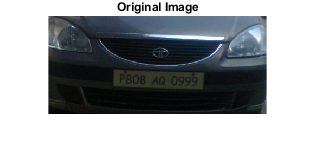

img_path = "images/final/task_3/";

image1 = imread(img_path + "example_number_plate.png");
imshow(image1); title("Original Image");

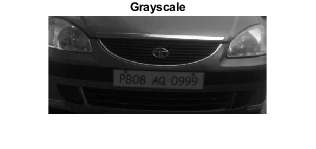


img1gray = rgb2gray(image1);
imshow(img1gray); title("Grayscale");

### Noise removal

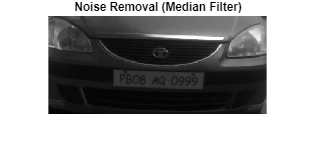

% Here I guess we could use imbilatfilt to filter it 
% bilaterally like in the documentation.
img1med = medfilt2(img1gray);
imshow(img1med); title("Noise Removal (Median Filter)");

### Contrast Enhancement 

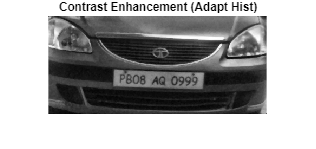

img1cont = adapthisteq(img1med);
imshow(img1cont); title("Contrast Enhancement (Adapt Hist)");

## Morphological Opening and Image Subtraction Operations

### Opening with 'disk'

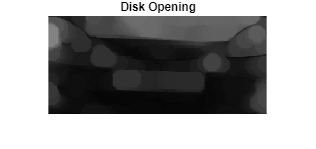

se = strel('disk',15);
img1open = imopen(img1cont,se);
imshow(img1open); title("Disk Opening");

### Subtraction from enhanced image

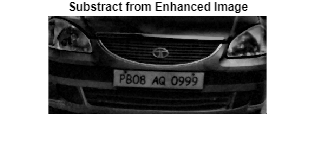

img1sub = imsubtract(img1cont, img1open);
imshow(img1sub); title("Substract from Enhanced Image");

## Image binarization

% Find grayscale threshold and binarize
bins = 19;
[counts,x] = imhist(img1sub, bins);
g_thresh = otsuthresh(counts) %graythresh(img1sub)

g_thresh = 0.1667

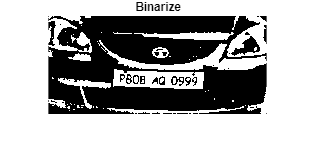


img1bin = imbinarize(img1sub, g_thresh);

%imshowpair(img1bin, img1bin_filled); 
imshow(img1bin);
title("Binarize");

## Creating Mask

### Detect edges with the Sobel operator

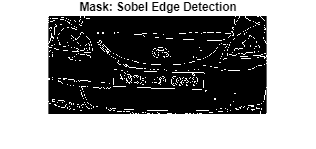

img1edge = edge(img1bin);
imshow(img1edge); title("Mask: Sobel Edge Detection");

### Candidate plate area detection with morphological operators

#### Dilation

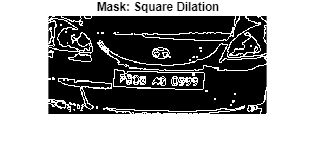

se2 = strel('square', 2);
img1dil = imdilate(img1edge, se2);
imshow(img1dil); title("Mask: Square Dilation");

#### Filling holes

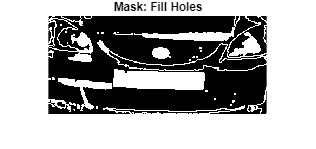

img1fill = imfill(img1dil, 'holes');
imshow(img1fill); title("Mask: Fill Holes");

#### Opening

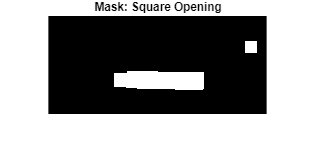

se3 = strel('square',22);
img1open = imopen(img1fill, se3);
imshow(img1open); title("Mask: Square Opening");

#### Remove smaller objects

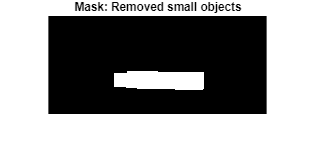

img1clean = bwareaopen(img1open, 800);
imshow(img1clean); title("Mask: Removed small objects");


% This does not seem necessary.
%se4 = strel('square', 4);
%img1erode = imerode(img1open, se4);
%imshow(img1erode); title("Square Erosion");

### Apply Mask

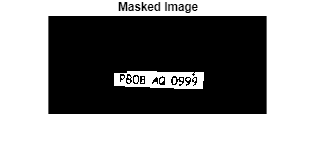

img1bin(~img1clean) = 0;
imshow(img1bin); title("Masked Image");

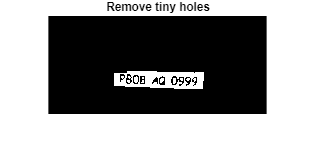


% Remove tiny holes based on size (screws at the top of plate)
img1bin_filled = ~bwareaopen(~img1bin, 20);
imshow(img1bin_filled); title("Remove tiny holes");

## OCR

Should make it only check for 

- Letters (Language) for the first 2 letters

- Numeric for the following 2 letters

- Letters for the middle 2 letters

- Numeric digits for the last 4 digits

% Crop region of text if needed
%crop_rec = [0.5 0.5 x y];

% Resize image (bigger) to make it easier for OCR
%img1bin_resized = imresize(img1bin, 3);
%imshow(img1bin_resized); title("Resized for OCR");

img_ocr = img1bin_filled;

% By default the ocr function's TextLayout will return a separate word for each set of
% letters that are separated by some space.
first_2_letters = "[N/A]";
middle_2_letters = "[N/A]";
ocr_words_letters = ocr(img_ocr, 'CharacterSet', 'A':'Z');
if (size(ocr_words_letters) >= 1)
    first_2_letters = ocr_words_letters.Words{1}(1:2);
    middle_2_letters = ocr_words_letters.Words{2};
end

first_2_digits = "[N/A]";
last_4_digits = "[N/A]";
ocr_words_digits = ocr(img_ocr, 'CharacterSet', '0123456789');
if (size(ocr_words_digits) > 0)
    first_2_digits = ocr_words_digits.Words{1}(3:4);
    last_4_digits = ocr_words_digits.Words{3};
end

disp(first_2_letters + "" + first_2_digits + " " + middle_2_letters + " " + last_4_digits);

PB08 AQ 0999



fclose('all');